# Fourier Transform based signal analysis

[BE503 - 2021 - Lab 5 - Fourier Analysis based Signal Processing ](https://github.com/SrikanthS-IIT/BE503-AugDec2021/blob/main/BE503_2021_Lab5_Fourier%20Transform%20based%20signal%20analysis.mlx)© 2021 by [Srikanth Sugavanam ](https://www.srikanthsugavanam.com/)is licensed under [CC BY-NC 4.0    ](http://creativecommons.org/licenses/by-nc/4.0/?ref=chooser-v1)

## About the MATLAB Workbook Environment

The MATLAB workbook environment combines rich text, MATLAB code and its outputs under a single roof. This means you don't have to go back and forth between a text editor and MATLAB to document your outputs. You can use the Text toggle to enter rich text, or...

%You can use the code toggle to enter code like this.

The outputs are either presented below the code, or on the side, as you choose to view this. 

## Today's lab

In today's lab, we will be exploring how to use the FFT function of MATLAB to carry out Fourier Transform operations. I have provided example MATLAB codes for the FFT and filter implementation, which you can copy paste to implement the indicated tasks. 

## Basics

The following is a code that generates a sine function.

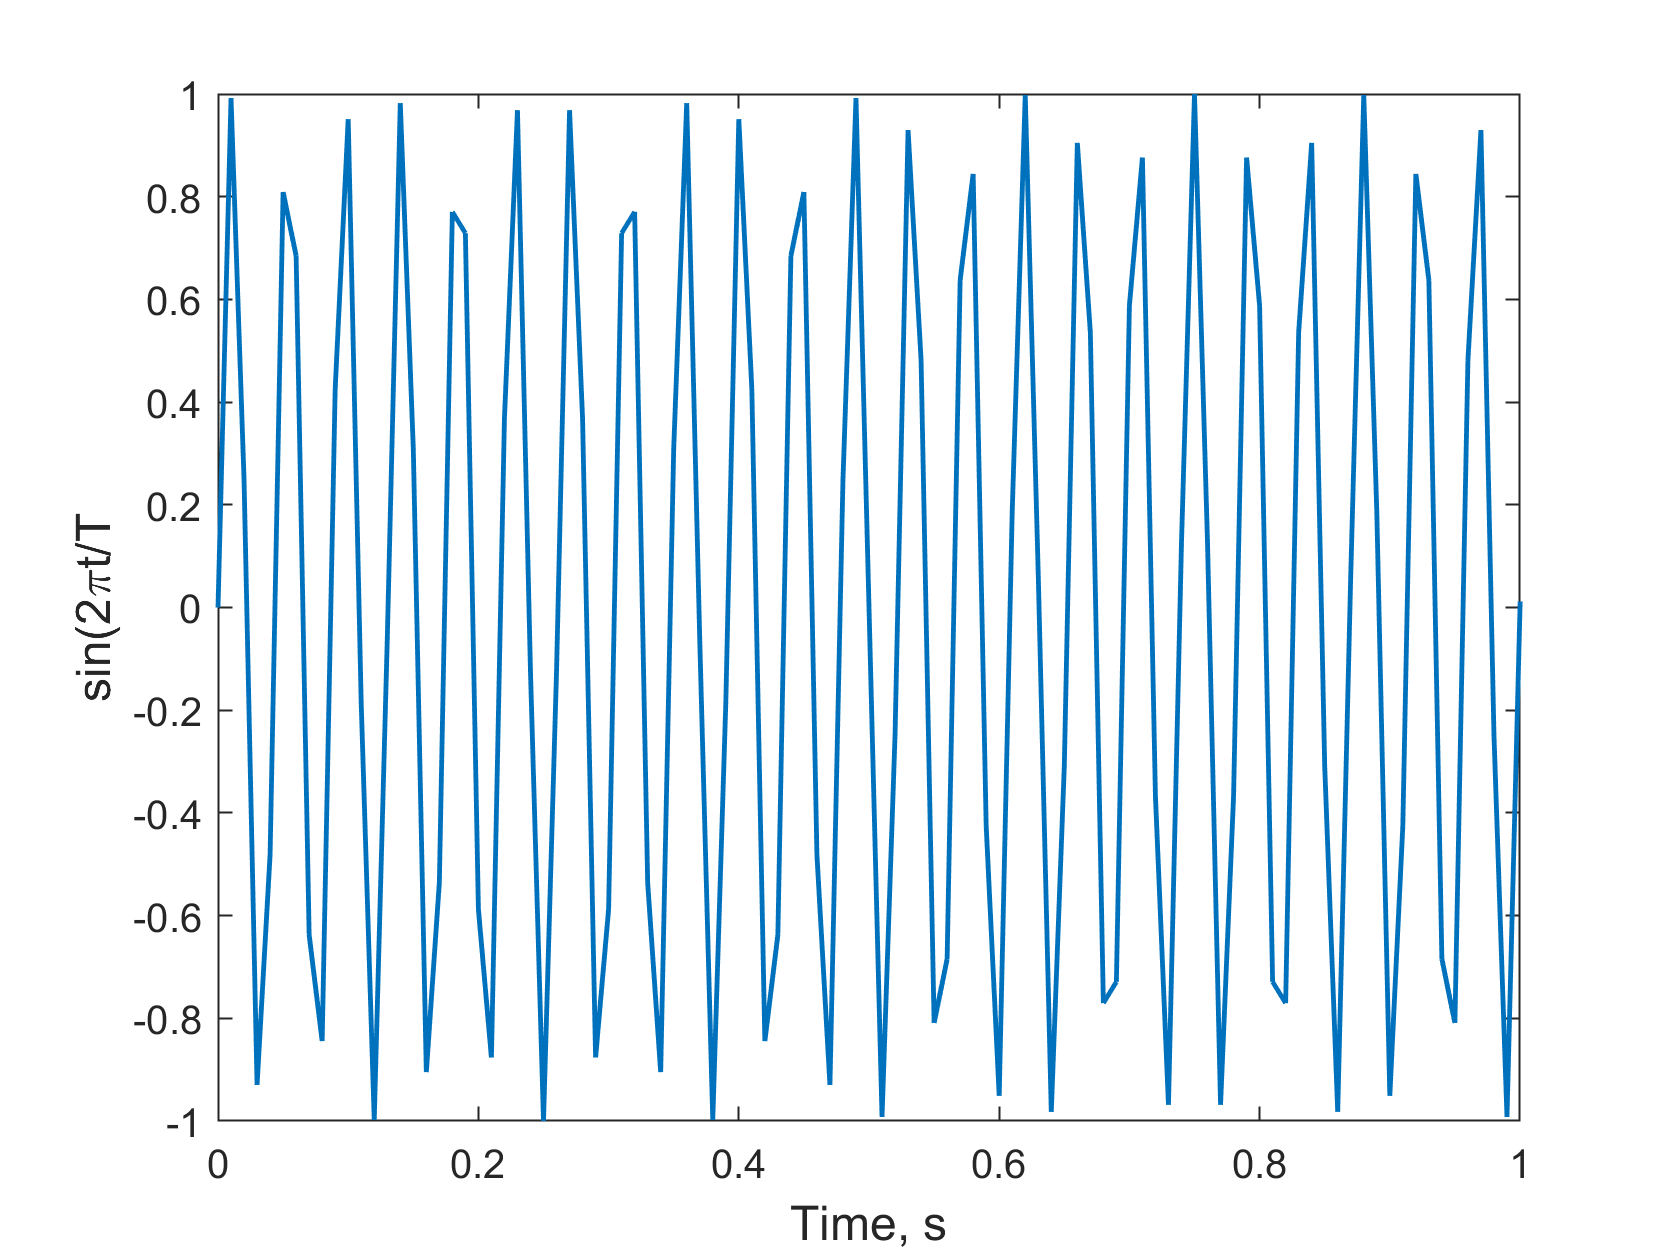

t = 0:1/50/2:50;
T = 1/23;
y = sin(2*pi*t/T);

plot(t,y,'Linewidth',1.2);
xlabel('Time, s', 'Fontsize',12);
ylabel('sin(2\pit/T','FontSize',12)
xlim([0 1])

%Press 'Run Section' if you don't see any output. 

We know that the frequency of this sine wave is 1/T, and so if we take the Fourier Transform of this signal, we expect to get two peaks in the frequency domain - one for positive, and the other corresponding to the negative frequency component. This is due to the use of the complex exponential Fourier kernel - a real world signal will have thus a complex frequency spectrum. For the purposes of signal analysis we will just stick to positive frequencies, as we know the negative frequencies will its complex conjugate. 

The Fourier transform code and its output are shown below. Zoom in to see the frequency peak, and check if it is happening at the right frequency. 

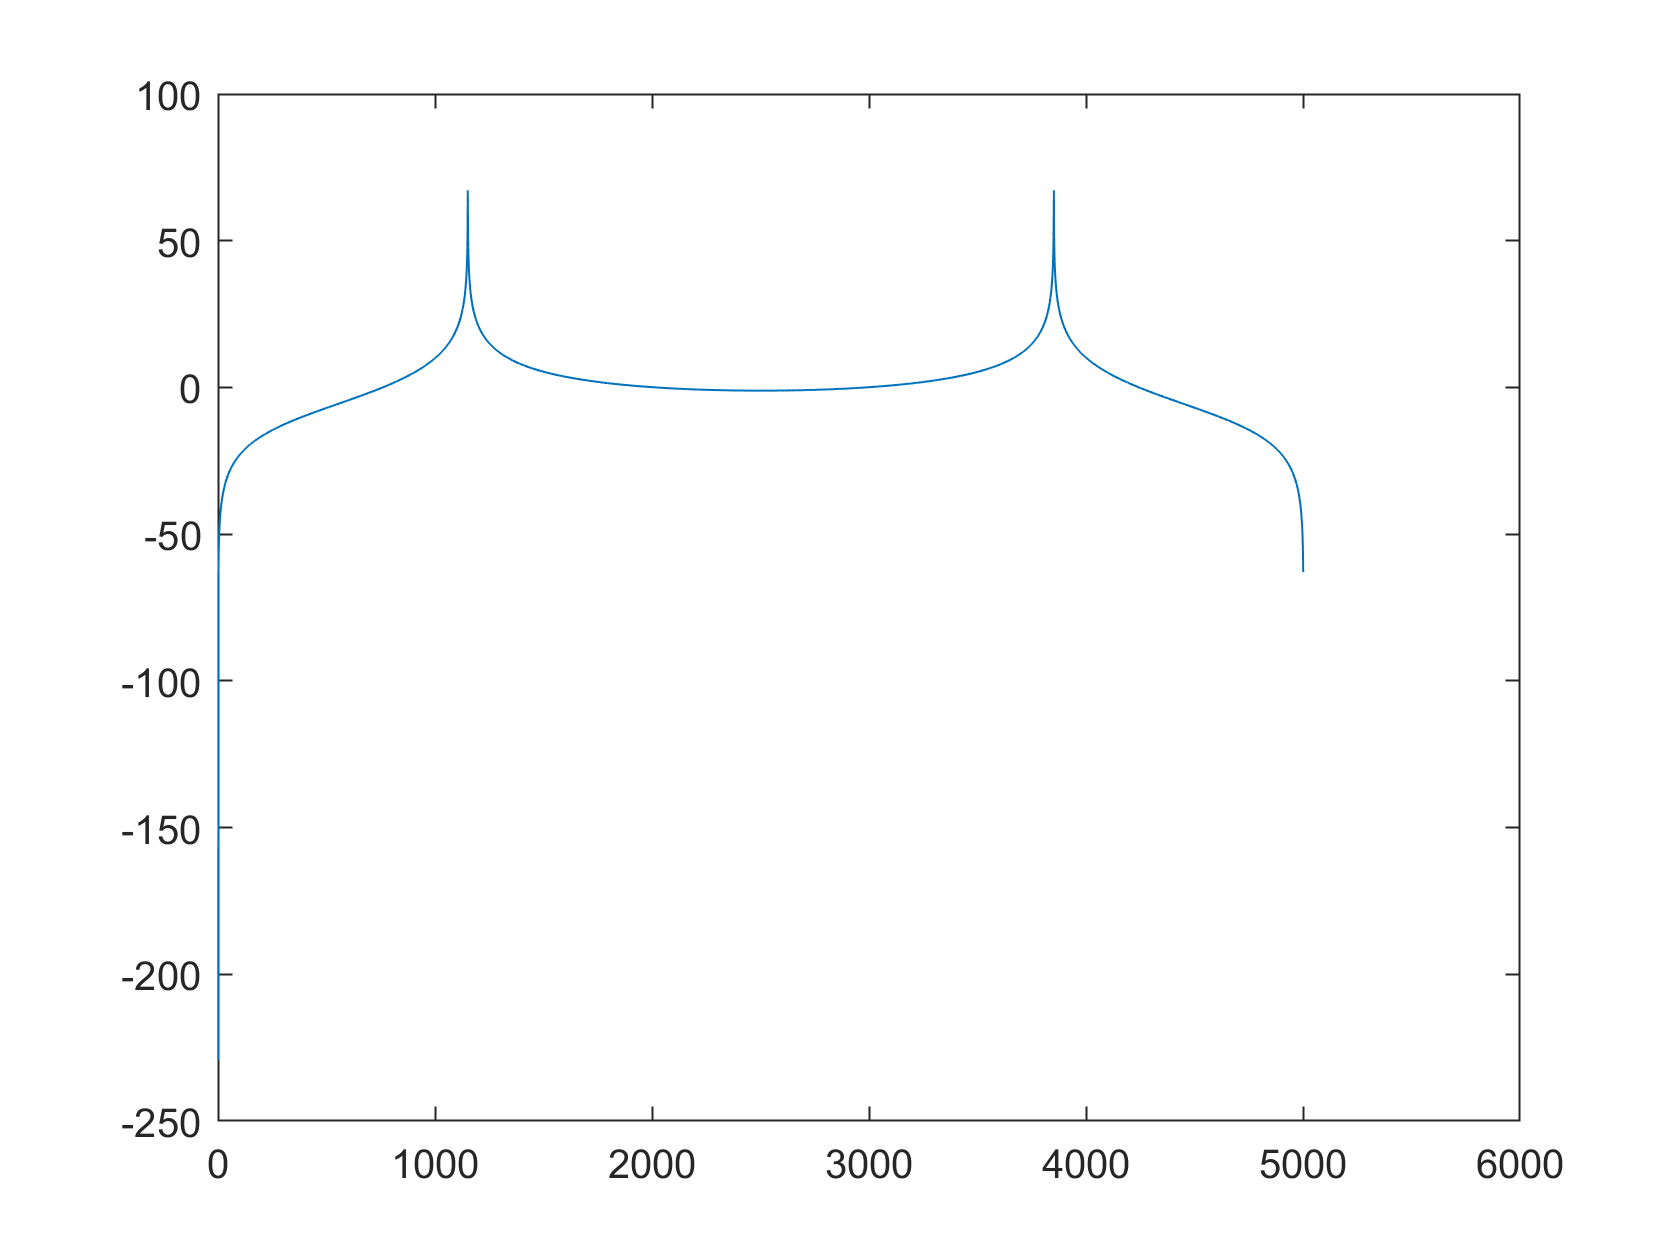

fftsig = fft(y);
plot(20*log10(abs((fftsig))));

Note how the FFT function outputs the positive and negative frequencies as being flipped. There are two peaks, corresponding to the positive frequency (near 1), and the negative frequency (near 4000). 

If we want to just see the signal spectral content, we can work with just the positive frequencies, so we will crop it as shown in the code below. For filtering operations, we will need both positive and negative frequencies. 

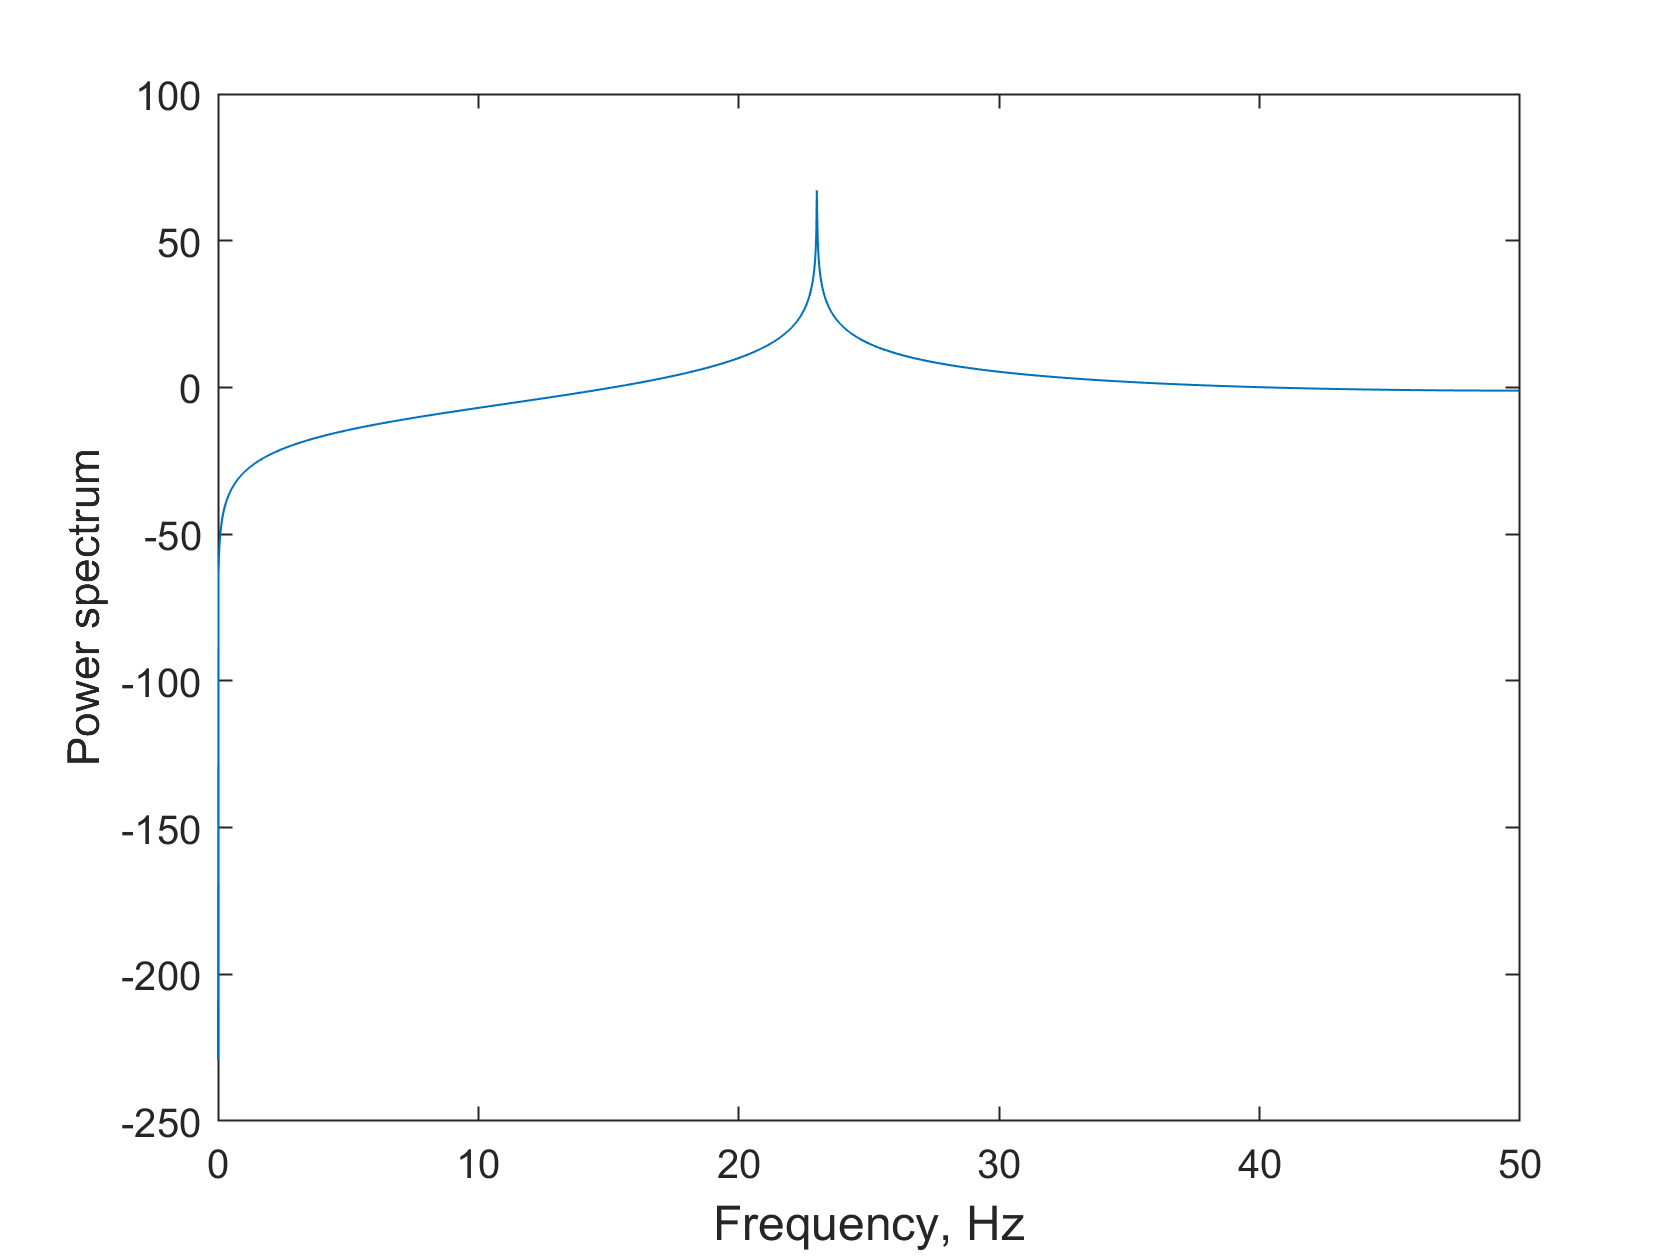

fftsig_crop = fftsig(1:floor(length(fftsig)/2));

%Defining the frequency axis
dt = 1/50/2;
df = 1/(length(y)*dt);

f = 0:df:1/dt/2-df;

figure(2);
plot(f,20*log10(abs(fftsig_crop)));
xlabel('Frequency, Hz','FontSize',12);
ylabel('Power spectrum');


%Press 'Run Section' if you don't see any output, or if you want to run the
%code again. 

Note how we are plotting the 20.log10() of the absolute value. This is directly getting to the power spectrum. 

You can use the above codes to do the following exercises. 

## Task 1 - Making filters in the frequency domain.

The simplest filters are rectangular, with no phase profile, and transmitting a subset of frequencies. 

The code below shows how you can make a simple low pass filter with a cut off at a predefined frequency $f_{c\;}$. Note that now we have to operate on both positive and negative frequencies. 

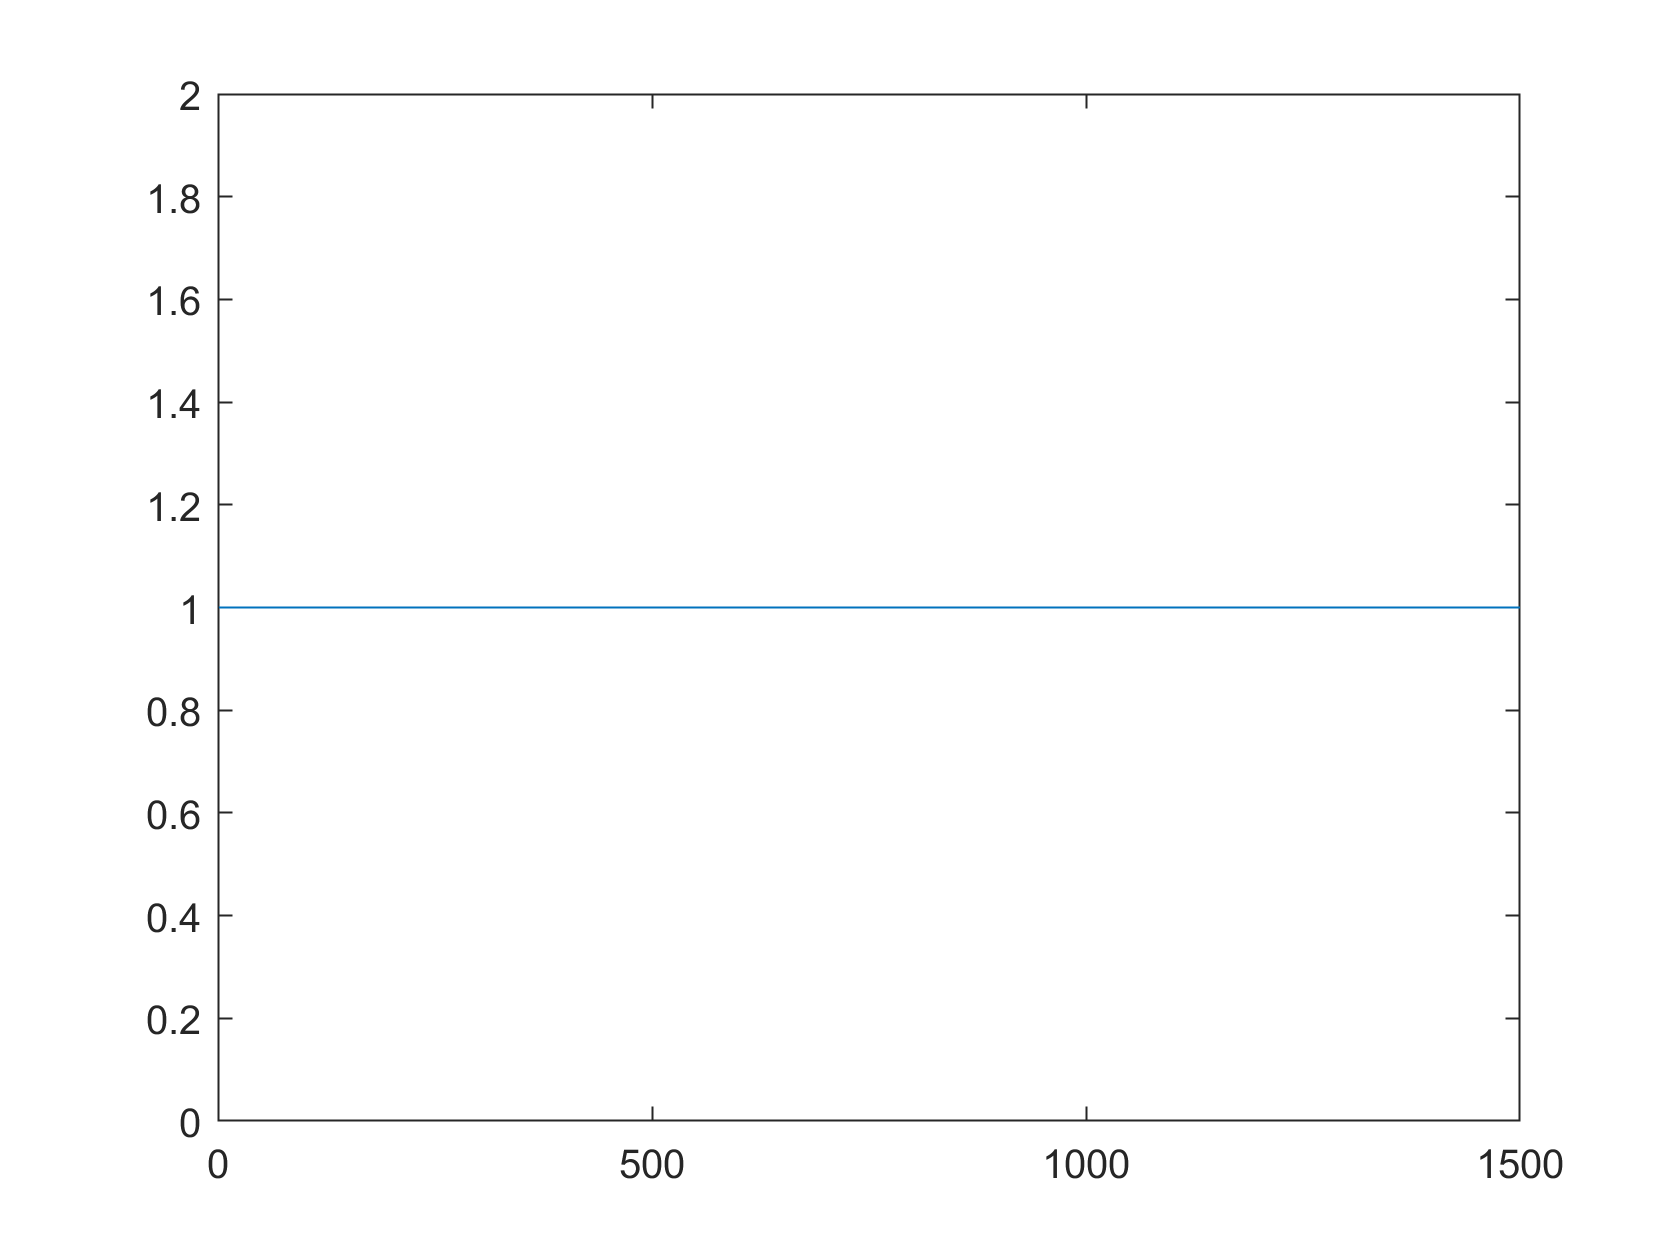

fc = 30; %30 Hz cutoff

%Create an array of length fc/df
window = ones(1, floor(fc/df));
plot(window)

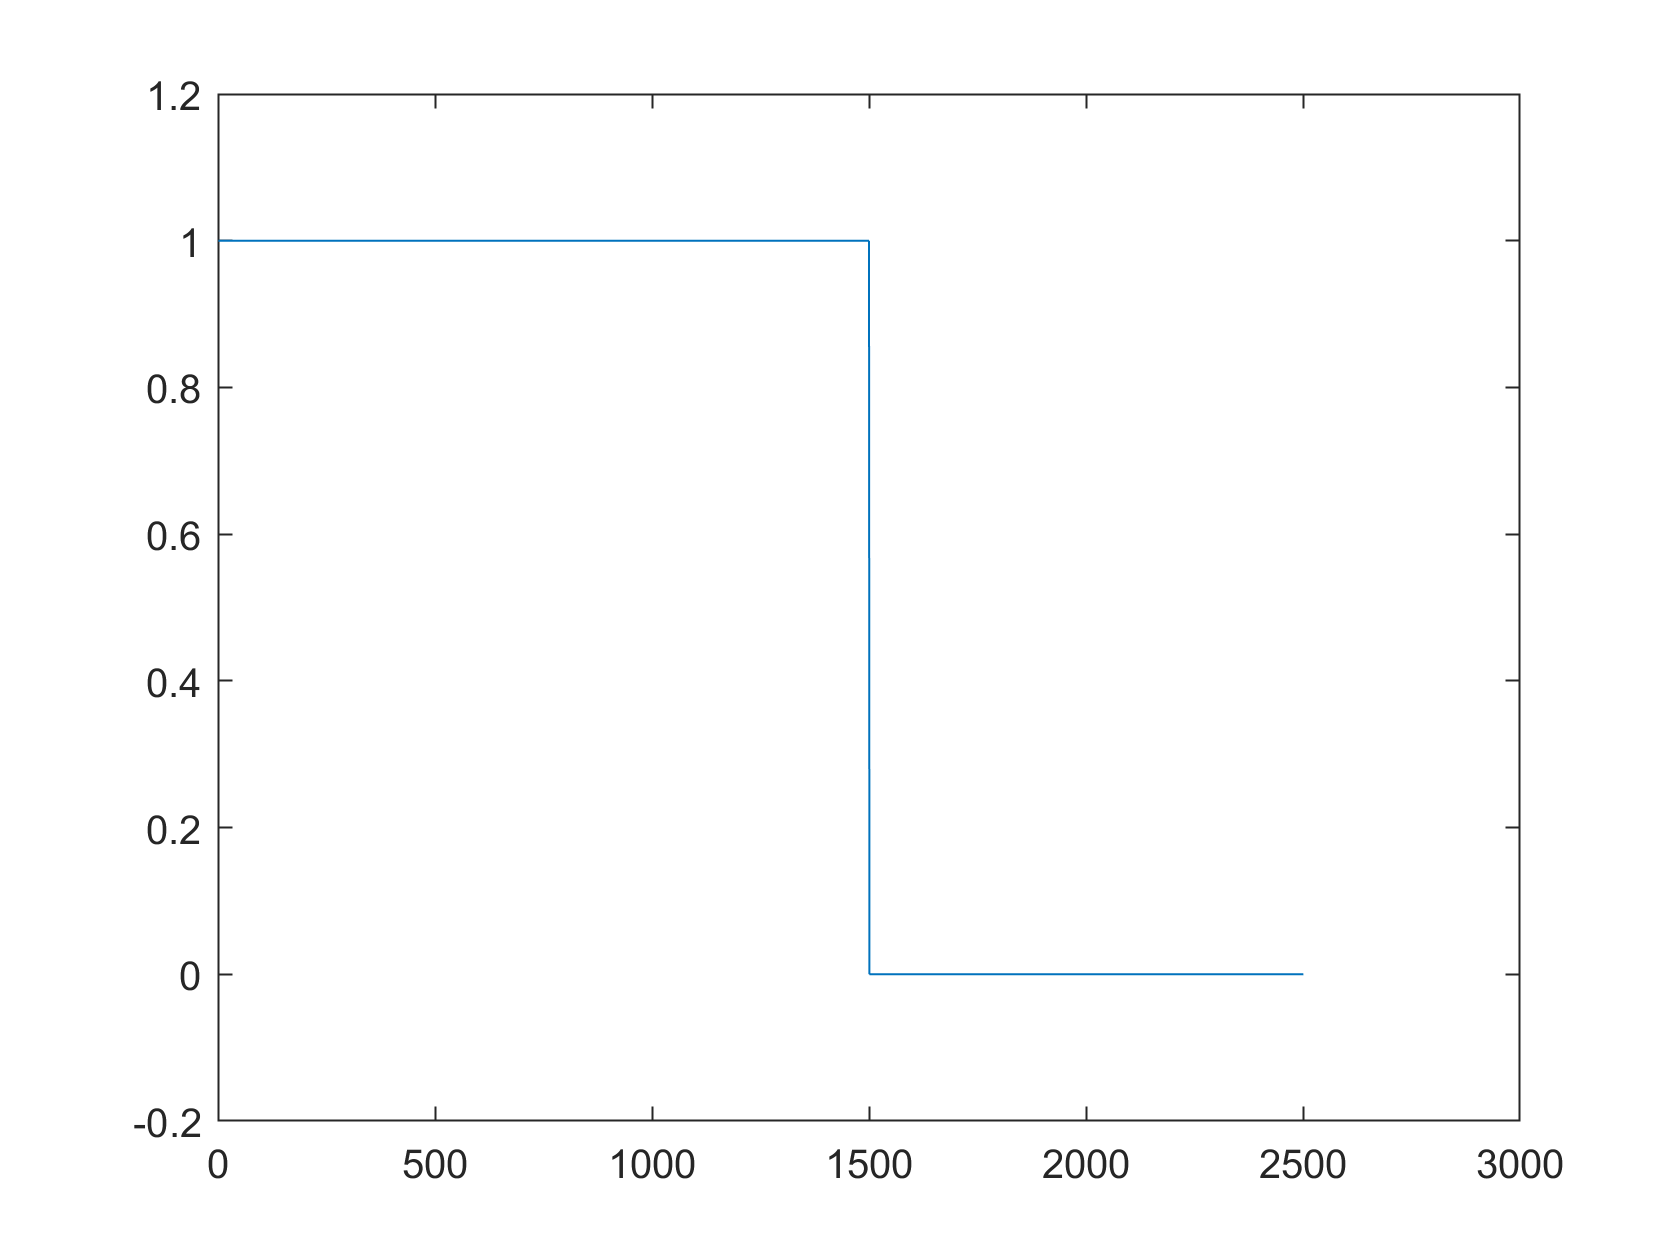


%Create a filter function that is as large as the single-sided FFT, where
%the filter value drops to zero after the cut-off frequency.
filter = [window, ones(1,length(f)-length(window)+1)*1E-9];
plot(filter)
ylim([-0.2 1.2])

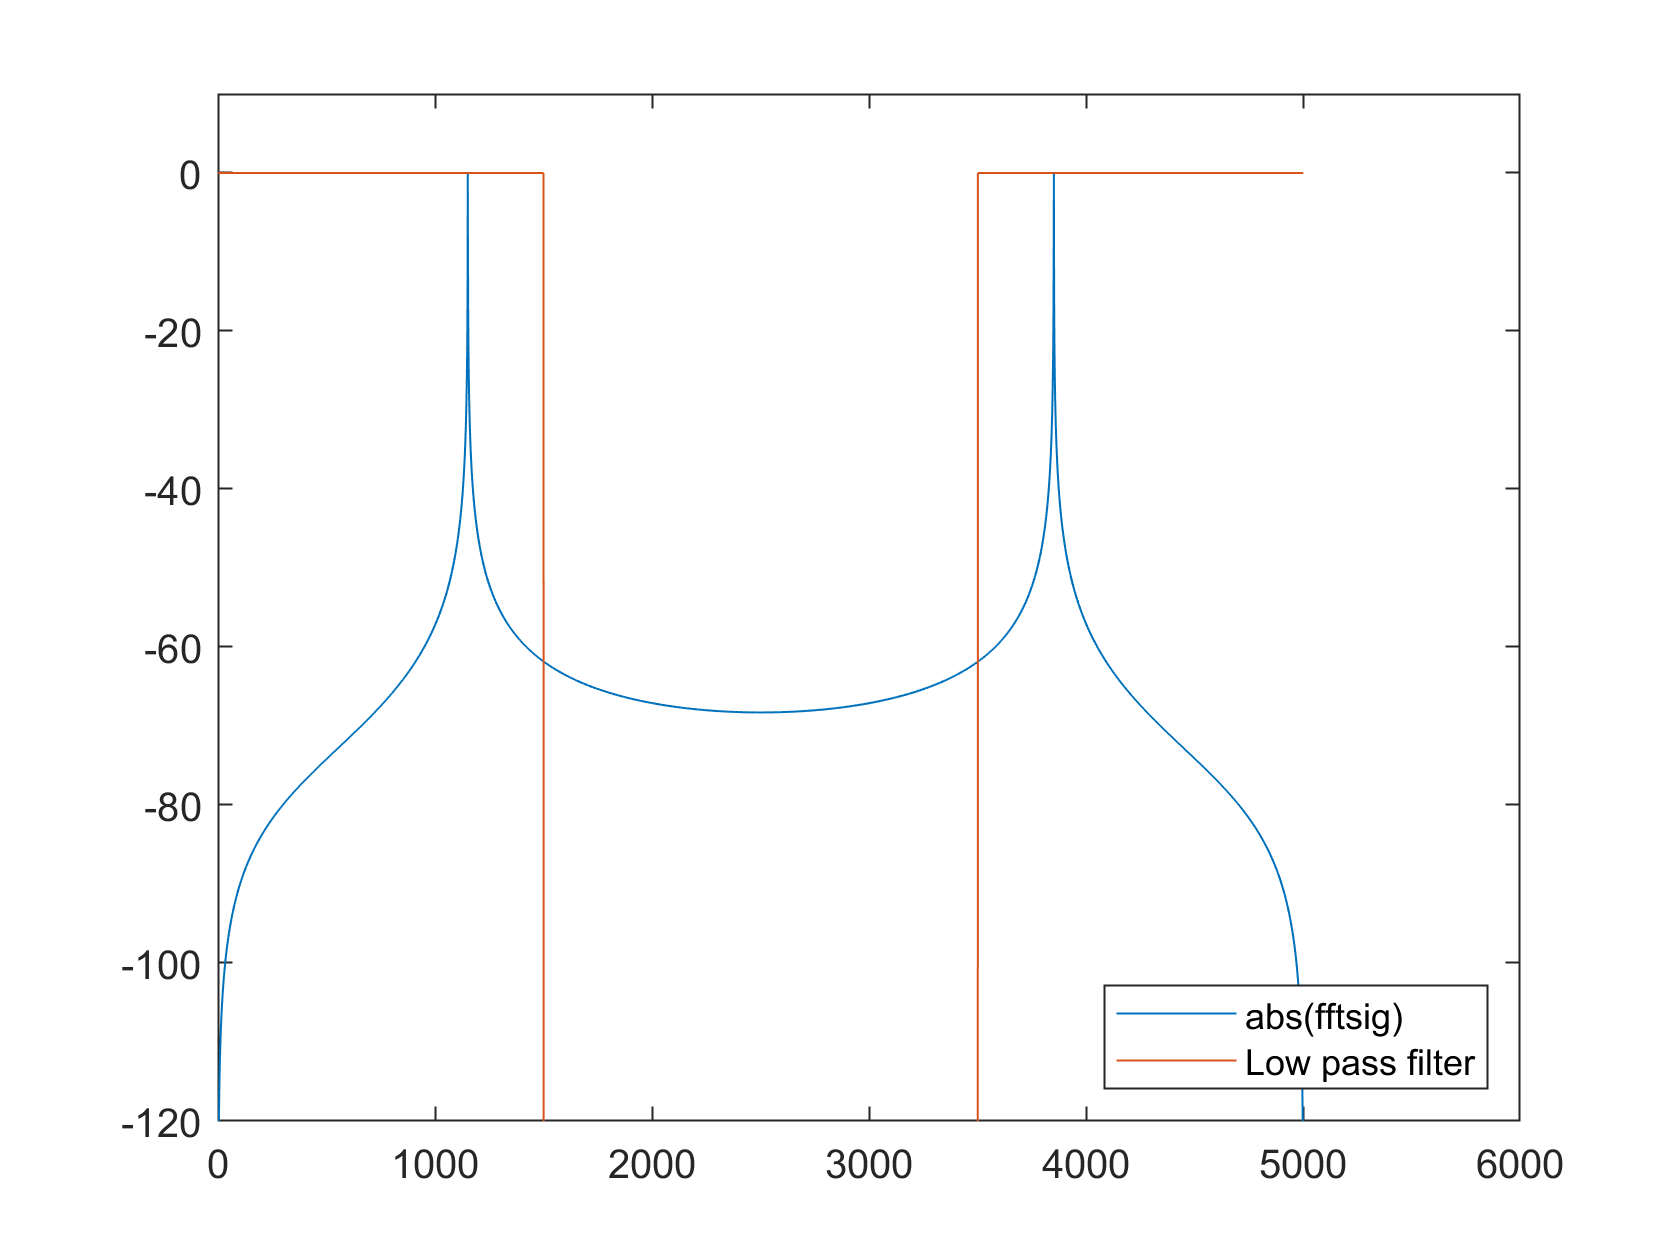


%Create a flipped double sided filter to filter both positive and negative
%frequency components.
filter = [filter, fliplr(filter(1:end-1))];

%Plot the results to see if it is filtering properly
plot(20*log10(abs(fftsig))-max(20*log10(abs(fftsig))));
hold on;
plot(20*log10(filter));
hold off
ylim([-120 10])
legend('abs(fftsig)','Low pass filter','Location',"southeast");

Check the dimensions of the calculated filter and fftsig functions. Note that I have normalized the FFT signal to show the filter more prominently. This step is not necessary when performing the actual filtering operation. 

As the filter and fftsig are of the same size, we can now perform and element-wise multiplication in the frequency domain to carry out the filtering operation. 

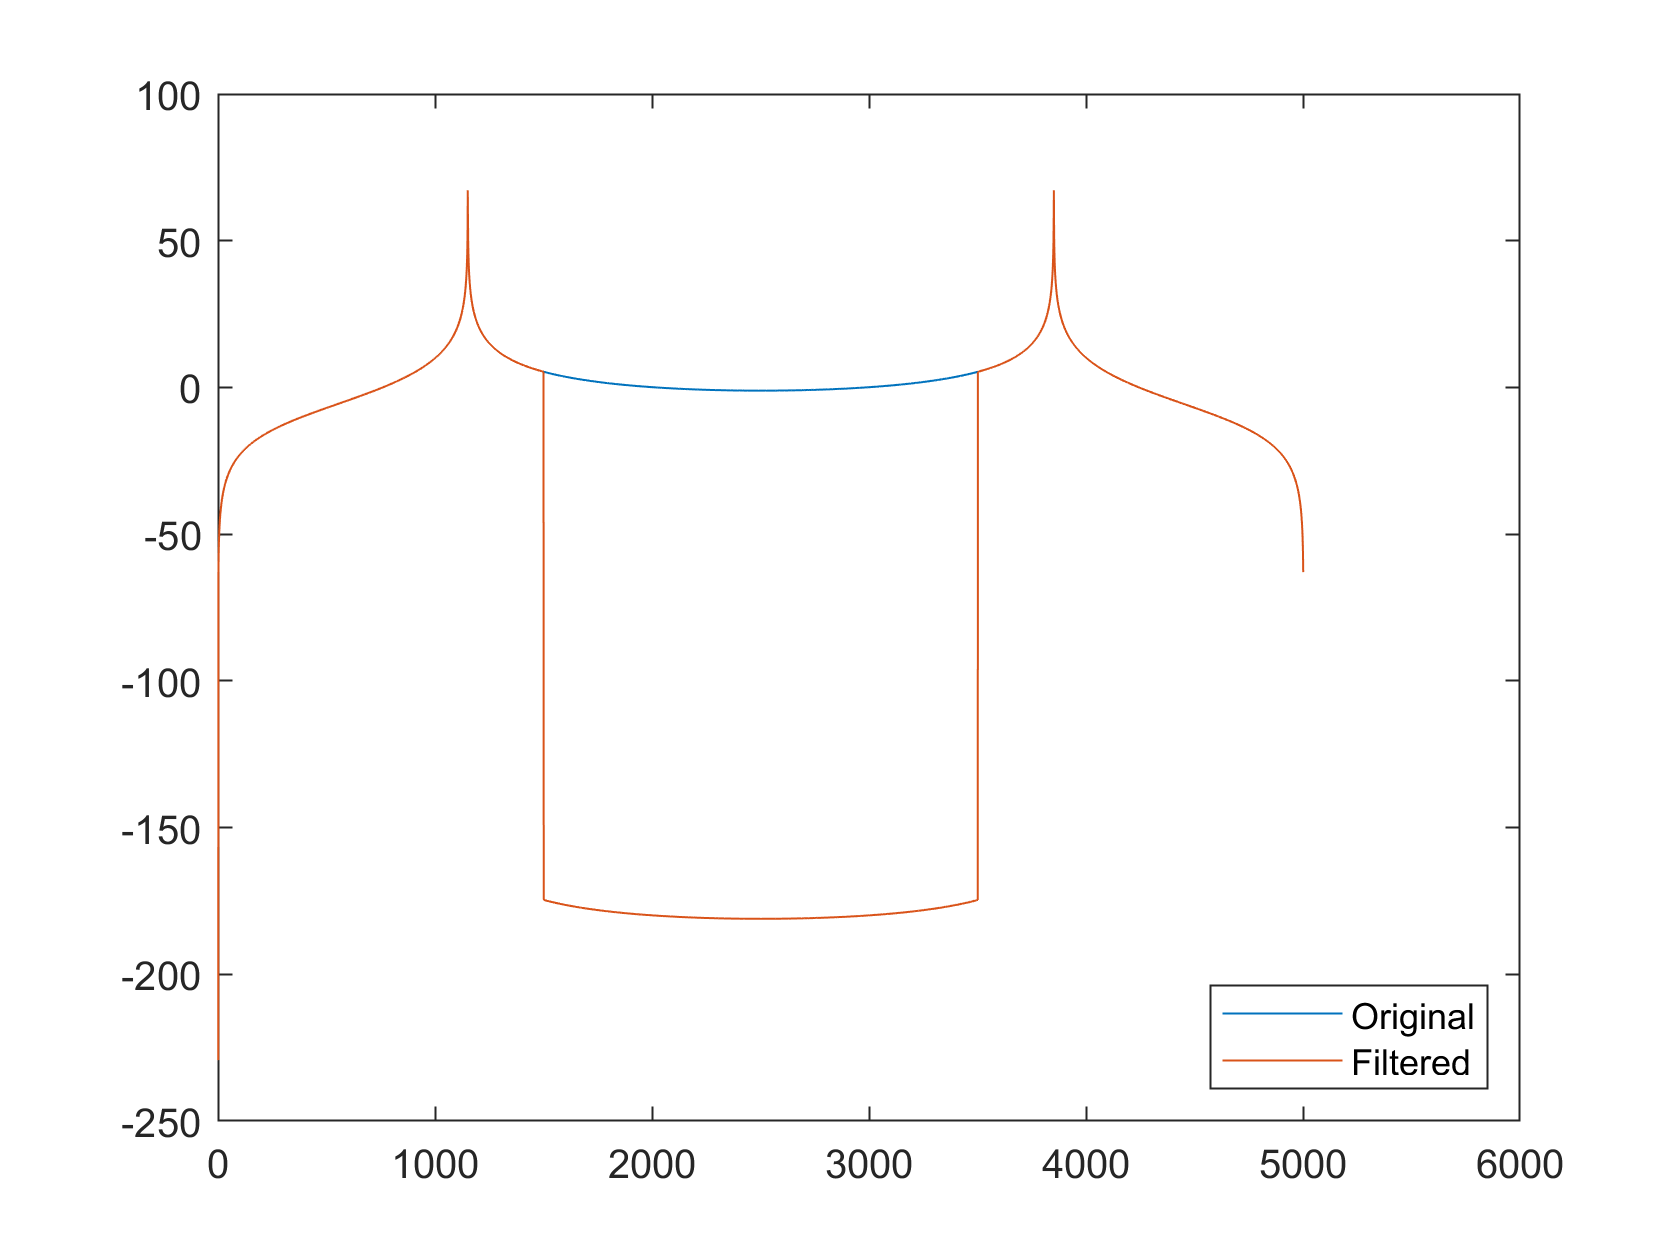

filt_fftsig = fftsig.*filter;
plot(20*log10(abs(fftsig)));
hold on;
plot(20*log10(abs(filt_fftsig)));
hold off;
legend('Original','Filtered','location',"southeast");

Calculating the Inverse Fourier Transform

Now that you have your filtered signal, you can go back to the time domain by calculating the Inverse Fourier Transform. 

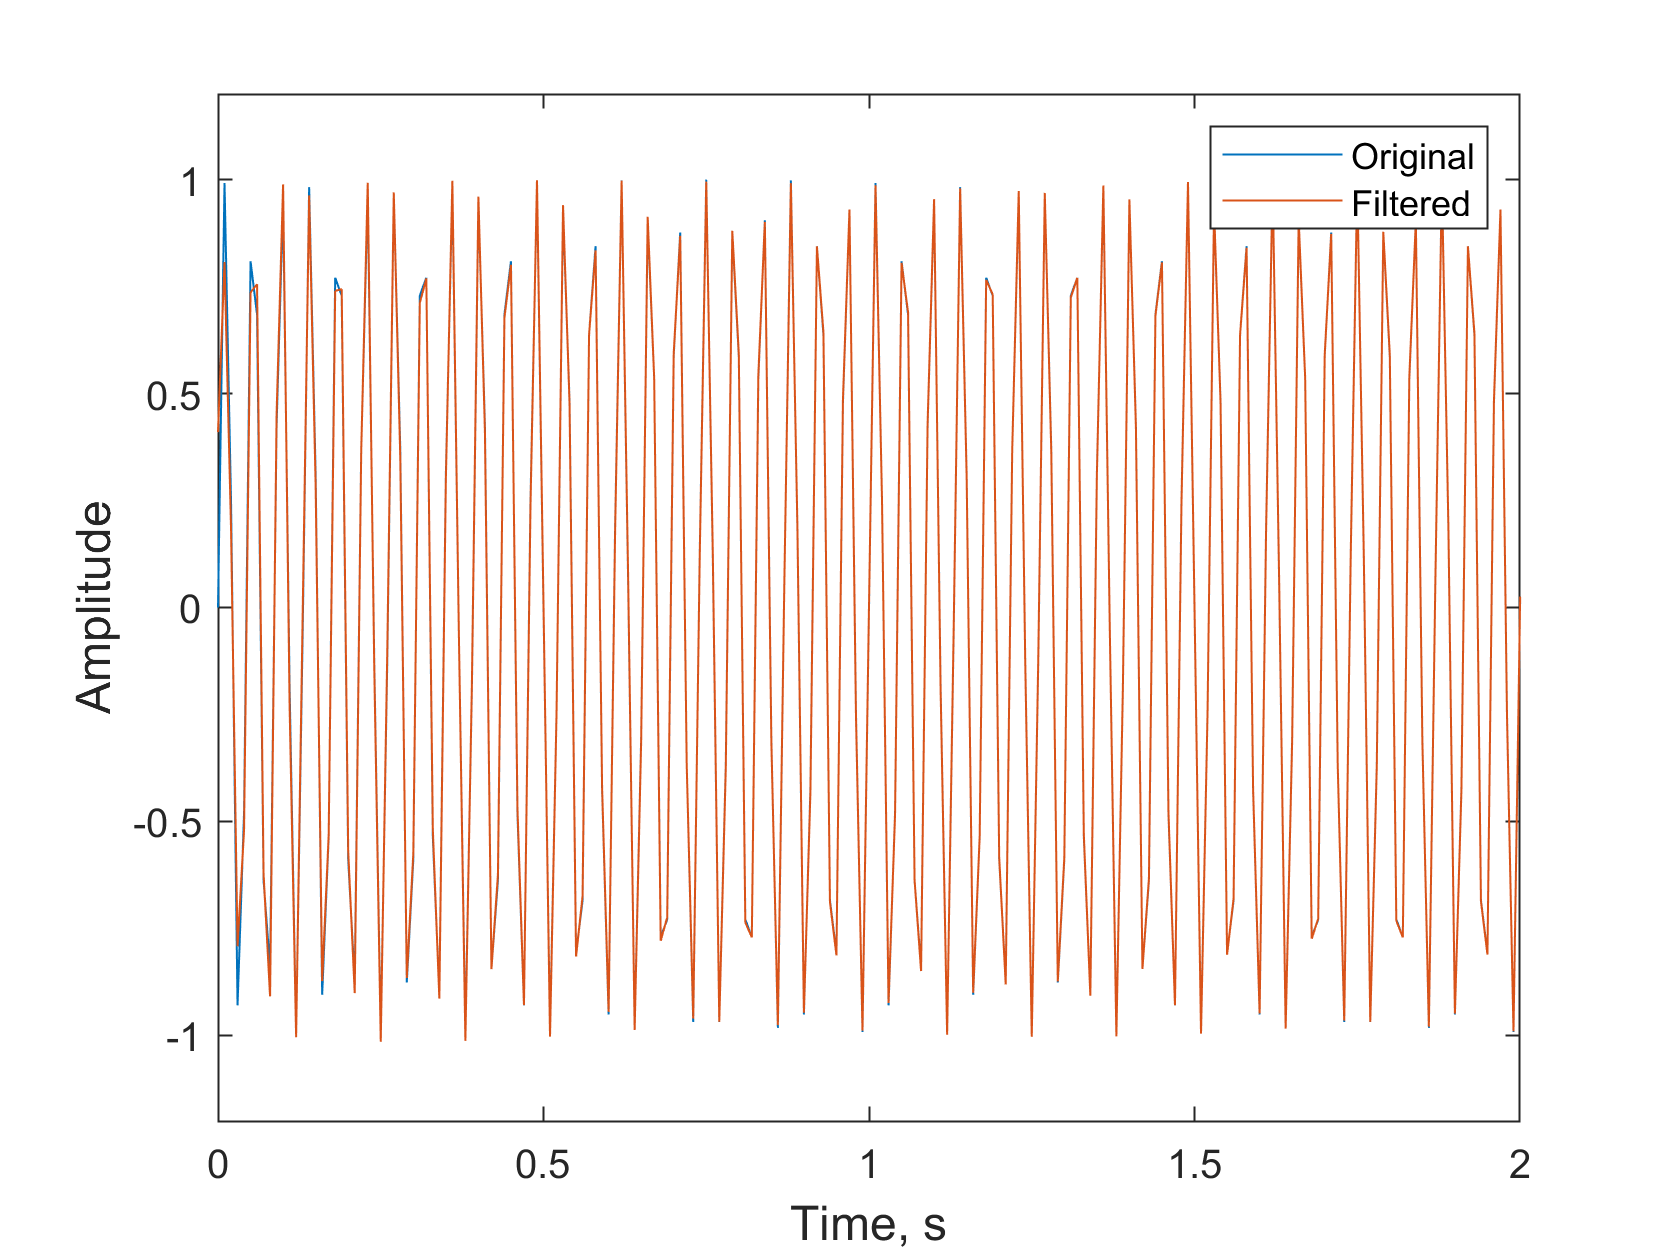

filt_sig = ifft(filt_fftsig); %note the use of complex valued filtered function for the IFFT.
plot(t,y,t,real(filt_sig)); %We drop the imaginary parts, as it amounts to less than 0.1 mrad of phase deviation over time.

xlabel('Time, s','Fontsize', 12);
ylabel('Amplitude','FontSize',12);
xlim([0 2]);
ylim([-1.2 1.2]);
legend('Original','Filtered','location','northeast')

### Task 1a. Make a rectangular high pass filter with cut-off at 50 Hz. 

Insert your code in the box below, and press the '**Run Section**' button above. 

%%Insert your code here

### Task 1b. Make a band pass filter with a bandwidth of 5 Hz, and centered at 50 Hz. 

%%Insert your code here

***Tip ****- Ensure that when you write the code, you can make an arbitrary band pass filter with an arbitrary bandwidth, for any input value. *

## Task 2 - ECG signal conditioning and analysis

Import the ECGData file into the MATLAB workspace using the load command below. You have to enter the path where you have downloaded the ECGData. 

load('filelocation_withfullpath');
%eg load('C:\Srikanth\MATLAB Code\ECGData.mat');

### Task 2a. Detrending

Use a high pass filter to detrend the ECG. Explain your choice for the filter cut-off. 

Steps you have to perform. 

- Take the ECG signal to Fourier domain.

- Design the high pass filter.

- Multiply the ECG signal to the Filter function.

- Calculate the inverse Fourier transform of the filtered function.

- Compare the results. 

%Insert your code here

### Task 2b. Use a band-stop filter to remove the electronic noise component in the detrended ECG signal. 

%Insert your code here

### Task 2c. Signal conditioning quality analysis

Overlay the original ECG signal provided with your signal conditioned output. How will you quantify the quality of your processed signal? Present and discuss your analysis. 

[BE503 - 2021 - Lab 5 - Fourier Analysis based Signal Processing ](https://github.com/SrikanthS-IIT/BE503-AugDec2021/blob/main/BE503_2021_Lab5_Fourier%20Transform%20based%20signal%20analysis.mlx)© 2021 by [Srikanth Sugavanam ](https://www.srikanthsugavanam.com/)is licensed under [CC BY-NC 4.0    ](http://creativecommons.org/licenses/by-nc/4.0/?ref=chooser-v1)